# **PART 2: Modeling**

clear all
clc

# Exercise 2.1

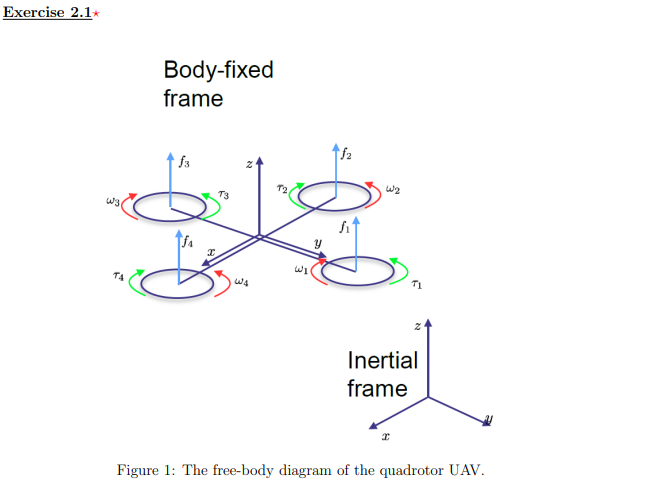

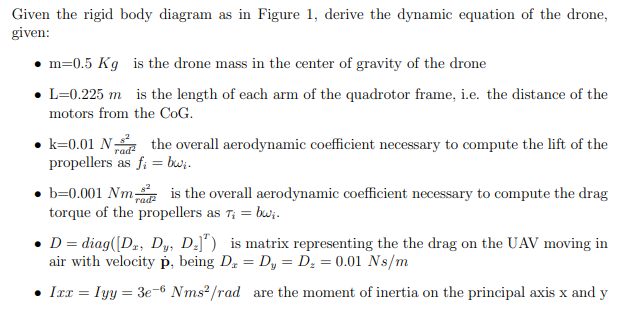

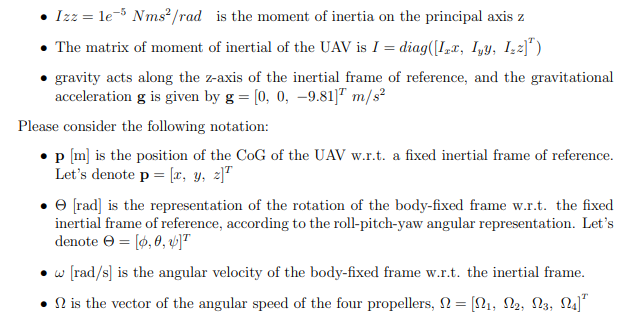

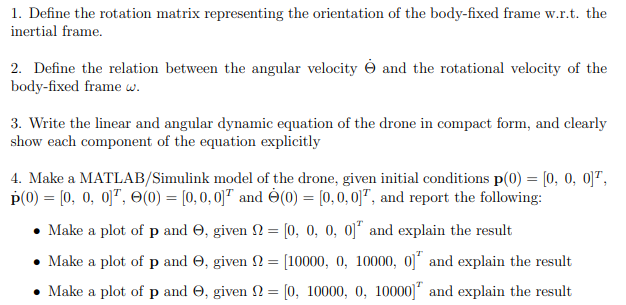

syms x y z phi theta psi theta_dot phi_a
m=0.5;    % m=0.5 Kg 
L=0.225;  %L=0.225 m 
k=0.01 ;  %N(s^2/rad^2)
b=0.001; %Nm(s^2/rad^2)
D=diag([0.01,0.01,0.01]'); %Ns/m
k_d=D;
Ixx=3*exp(-6);   %Nm(s^2/rad)
Iyy=3*exp(-6);   %Nm(s^2/rad)
Izz=1*exp(-5);   %Nm(s^2/rad)
I=diag([Ixx,Iyy,Izz]');
g=[0,0,-9.81]';  %m/s
%p_m=[x,y,z]'
%Theta=[phi,theta,psi]'


%1.
%Rotaion=rz*ry*rx
Rotation=[cos(psi)*cos(theta) cos(psi)*sin(theta)*sin(phi)-sin(psi)*cos(theta) cos(psi)*sin(theta)*cos(phi)+sin(psi)*sin(theta);...
          sin(psi)*cos(theta) sin(psi)*sin(theta)*sin(phi)-cos(psi)*cos(theta) sin(psi)*sin(theta)*cos(phi)+cos(psi)*sin(theta);...
          -sin(theta) cos(theta)*sin(phi) cos(theta)*cos(phi)]

$$Rotation = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{2} & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\sigma_{1} & \sin\left(\psi \right)\,\sin\left(\theta \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \sigma_{1} & \sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\sigma_{2} & \cos\left(\psi \right)\,\sin\left(\theta \right)+\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta \right)\,\sin\left(\psi \right)\\ \sigma_{2}=\cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}$$


R=rotz(psi)*roty(theta)*rotx(phi)

$$R = \left(\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$

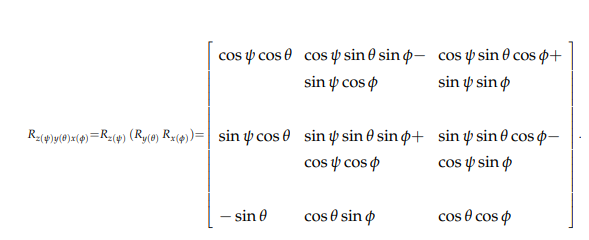

%2.
theta_dot = [1, sin(phi)*tan(theta), cos(phi)*tan(theta);
            0, cos(phi), -sin(phi);
            0,sin(phi)/cos(theta), cos(phi)/cos(theta)]

$$theta\_dot = \left(\begin{array}{ccc} 1 & \sin\left(\varphi \right)\,\tan\left(\theta \right) & \cos\left(\varphi \right)\,\tan\left(\theta \right)\\ 0 & \cos\left(\varphi \right) & -\sin\left(\varphi \right)\\ 0 & \frac{\sin\left(\varphi \right)}{\cos\left(\theta \right)} & \frac{\cos\left(\varphi \right)}{\cos\left(\theta \right)} \end{array}\right)$$

w_arrow=[1 0 -sin(theta); 0 cos(phi) cos(theta)*sin(phi); 0 -sin(phi) cos(theta)*cos(phi)]*theta_dot

$$w\_arrow = \left(\begin{array}{ccc} 1 & \sin\left(\varphi \right)\,\tan\left(\theta \right)-\frac{\sin\left(\varphi \right)\,\sin\left(\theta \right)}{\cos\left(\theta \right)} & \cos\left(\varphi \right)\,\tan\left(\theta \right)-\frac{\cos\left(\varphi \right)\,\sin\left(\theta \right)}{\cos\left(\theta \right)}\\ 0 & {\cos\left(\varphi \right)}^{2}+{\sin\left(\varphi \right)}^{2} & 0\\ 0 & 0 & {\cos\left(\varphi \right)}^{2}+{\sin\left(\varphi \right)}^{2} \end{array}\right)$$

%3. 
syms i w x_dot y_dot z_dot w1 w2 w3 w4 wx wy wz
F_B=k*[0;0;symsum(w^2,i,1,4)]

$$F\_B = \left(\begin{array}{c} 0\\ 0\\ \frac{w^{2}}{25} \end{array}\right)$$

F_D=-k_d*[x_dot;y_dot;z_dot] % what exactly is kd

$$F\_D = \left(\begin{array}{c} -\frac{\dot{x}}{100}\\ -\frac{\dot{y}}{100}\\ -\frac{\dot{z}}{100} \end{array}\right)$$

%linear dynamics equation
x_ddot=(-m*g+R*F_B+F_D)/m

$$x\_ddot = \left(\begin{array}{c} \frac{2\,w^{2}\,\left(\sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\right)}{25}-\frac{\dot{x}}{50}\\ -\frac{\dot{y}}{50}-\frac{2\,w^{2}\,\left(\cos\left(\psi \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\right)}{25}\\ \frac{2\,\cos\left(\varphi \right)\,\cos\left(\theta \right)\,w^{2}}{25}-\frac{\dot{z}}{50}+\frac{981}{100} \end{array}\right)$$

%angular dynamics equation
tau_b_phi=L*k*(w1^2-w3^2);
tau_b_theta=L*k*(w2^2-w4^2);
tau_b_psi=b*(w1^2-w2^2+w3^2-w4^2);

w_dot_x=tau_b_phi*(Ixx^-1)-(((Iyy-Izz)/Ixx)*wy*wz);
w_dot_y=tau_b_theta*(Iyy^-1)-(((Izz-Ixx)/Iyy)*wx*wz);
w_dot_z=tau_b_psi*(Izz^-1)-(((Ixx-Iyy)/Izz)*wx*wy);
w_dot=vpa([w_dot_x;w_dot_y;w_dot_z])

$$w\_dot = \left(\begin{array}{c} 0.30257159511955133268656936706975\,{w_{1}}^{2}-0.30257159511955133268656936706975\,{w_{3}}^{2}-0.09390605718031828919034609270966\,\mathrm{wy}\,\mathrm{wz}\\ 0.30257159511955133268656936706975\,{w_{2}}^{2}-0.30257159511955133268656936706975\,{w_{4}}^{2}+0.09390605718031828919034609270966\,\mathrm{wx}\,\mathrm{wz}\\ 0.14841315910257659993476408999413\,{w_{1}}^{2}-0.14841315910257659993476408999413\,{w_{2}}^{2}+0.14841315910257659993476408999413\,{w_{3}}^{2}-0.14841315910257659993476408999413\,{w_{4}}^{2} \end{array}\right)$$

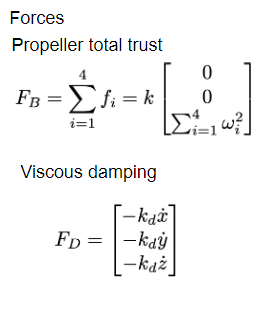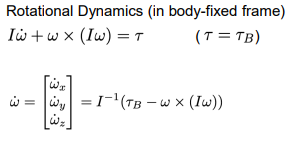

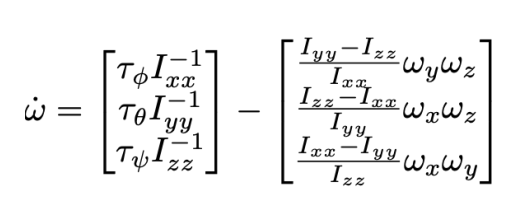

% %4.
% syms a b c d t
% p_0=[0 0 0]';
% p_dot_0=diff(p_0,t);
% theta_0=[0 0 0]';  
% %theta_dot_0=diff(theta_0,t);
% ORIENTATION = [theta_0];
% POSITION = [p_0];
% %omega=[0;0;0;0]';
% omega=[10000;0;10000;0]';
% %omega=[0;10000;0;10000]';
% 
% w_solve=subs(w_arrow,[theta phi],[theta_0(1) theta_0(2)])
% tau_b_phi=subs(tau_b_phi,[w1 w3],[omega(1) omega(3)]);
% tau_b_theta=subs(tau_b_theta,[w2 w4],[omega(2) omega(4)]);
% tau_b_psi=subs(tau_b_psi,[w1 w2 w3 w4],[omega(1) omega(2) omega(3) omega(4)]);
% tau_b=[tau_b_phi;tau_b_theta;tau_b_psi];
% w_dot=(pinv(I))*(tau_b-cross(w_solve,I*w_solve));
% 
% 
% F_B=k*[0;0;(omega(1)+omega(2)+omega(3)+omega(4))^2];
% F_D=-k_d*[p_dot_0(1);p_dot_0(2);p_dot_0(3)];
% %linear dynamics equation
% p_ddot=(-m*g+R*F_B+F_D)/m;
% time=0.001;
% theta_dot = [1, sin(phi)*tan(theta), cos(phi)*tan(theta);
%             0, cos(phi), -sin(phi);
%             0,sin(phi)/cos(theta), cos(phi)/cos(theta)]
% for time_run=1:7
%    phi=theta_0(1);
%    theta=theta_0(2);
%    psi=theta_0(3);
% 
%    R = rotz(psi)*roty(theta)*rotx(phi);
%    
%    p_ddot=(-m*g+R*F_B+F_D)/m;
%    p_dot_0=p_dot_0+p_ddot*time;
%    F_D=-k_d*[p_dot_0(1);p_dot_0(2);p_dot_0(3)];
%    p_0=p_0+p_dot_0*time+0.5*p_ddot*time^2;
%    POSITION=eval([POSITION,p_0]);
%    
%    w_dot=(pinv(I))*(tau_b-cross(w_solve,I*w_solve));
%    w_solve=w_solve+time*w_dot;
%    
%    theta_dot = [1, sin(phi)*tan(theta), cos(phi)*tan(theta);
%             0, cos(phi), -sin(phi);
%             0,sin(phi)/cos(theta), cos(phi)/cos(theta)]*w_solve;
%    theta_0=theta_0+theta_dot*time;
%    %theta_0(1) = wrapToPi(theta_0(1));
%    %theta_0(2) = wrapToPi(theta_0(2));
%    %theta_0(3) = wrapToPi(theta_0(3));
%    ORIENTATION=eval([ORIENTATION,theta_0])
% 
% end
% wrapToPi(ORIENTATION)


%%
%// inputs
% static: 11.0736x4
OMEGA = [0;10000;0;10000];
%// plot param
lim = 1e-2;
%// simulation param
running_time = 1e-2;
samp_time = 1e-3;
% initialization
m = 0.5;
L = 0.225;
k = 0.01;
b = 0.001;
D = diag([0.01,0.01,0.01]);
I = diag([3e-6, 3e-6, 1e-5]);
Euler = [0;0;0];
p = [0;0;0];
ORIENTATION = [Euler];
POSITION = [p];
dEuler = [0;0;0];
dp = [0;0;0];
g = [0;0;-9.81];
w = [1, 0, -sin(Euler(2));
    0, cos(Euler(1)), cos(Euler(2))*sin(Euler(1));
    0, -sin(Euler(1)), cos(Euler(2))*cos(Euler(1))]*dEuler;


iter = round(running_time/samp_time);
for i = 1:iter
    R = rotz(Euler(3))*roty(Euler(2))*rotx(Euler(1));
    ddp = (m*g+R*[0;0;k*sum(OMEGA.^2)]-D*dp)/m;
    % torque
    tau = [k*(OMEGA(1)^2-OMEGA(3)^2)*L;
        k*(OMEGA(2)^2-OMEGA(4)^2)*L;
        b*(OMEGA(1)^2-OMEGA(2)^2+OMEGA(3)^2-OMEGA(4)^2)];
    dw = pinv(I)*(tau-cross(w,I*w));
    % motion update
    %// position
    p = p+dp*samp_time+0.5*ddp*samp_time^2;
    dp = dp+ddp*samp_time;
    POSITION = [POSITION,p];
    
    %// orientation
    w = w+dw*samp_time;
    dEuler = [1, sin(Euler(1))*tan(Euler(2)), cos(Euler(1))*tan(Euler(2));
        0, cos(Euler(1)), -sin(Euler(1));
        0,sin(Euler(1))/cos(Euler(2)), cos(Euler(1))/cos(Euler(2))]*w
    Euler = Euler+dEuler*samp_time;
    Euler(1) = wrapToPi(Euler(1));
    Euler(2) = wrapToPi(Euler(2));
    Euler(3) = wrapToPi(Euler(3));
    ORIENTATION = [ORIENTATION,Euler];
end

dEuler = 	1.0e+07 *

         0
         0
   -2.0000


dEuler = 	1.0e+07 *

         0
         0
   -4.0000


dEuler = 	1.0e+07 *

         0
         0
   -6.0000


dEuler = 	1.0e+07 *

         0
         0
   -8.0000


dEuler = 	1.0e+08 *

         0
         0
   -1.0000


dEuler = 	1.0e+08 *

         0
         0
   -1.2000


dEuler = 	1.0e+08 *

         0
         0
   -1.4000


dEuler = 	1.0e+08 *

         0
         0
   -1.6000


dEuler = 	1.0e+08 *

         0
         0
   -1.8000


dEuler = 	1.0e+08 *

         0
         0
   -2.0000


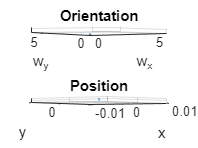


% show the result
figure;
subplot(2,1,1);
plot3(ORIENTATION(1,:), ORIENTATION(2,:), ORIENTATION(3,:));
xlabel('w_x');
ylabel('w_y');
zlabel('w_z');
xlim([0,2*pi]);
ylim([0,2*pi]);
zlim([0,2*pi]);
title("Orientation");
grid on;
subplot(2,1,2);
plot3(POSITION(1,:), POSITION(2,:), POSITION(3,:));
xlabel('x');
ylabel('y');
zlabel('z');
xlim([-lim,lim]);
ylim([-lim,lim]);
zlim([-lim,lim]);
grid on;
title("Position");

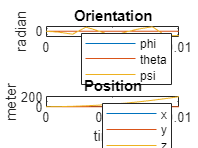

figure;
subplot(2,1,1);
plot([0:iter]*samp_time,ORIENTATION(1,:));
hold on;
plot([0:iter]*samp_time,ORIENTATION(2,:));
hold on;
plot([0:iter]*samp_time,ORIENTATION(3,:));
xlabel('time/s');
ylabel('radian');
legend('phi', 'theta', 'psi');
ylim([-pi,pi]);
title("Orientation");
subplot(2,1,2);
plot([0:iter]*samp_time,POSITION(1,:));
hold on;
plot([0:iter]*samp_time,POSITION(2,:));
hold on;
plot([0:iter]*samp_time,POSITION(3,:));
xlabel('time/s');
ylabel('meter');
legend('x', 'y', 'z');
title("Position");

# Exercise 2.2

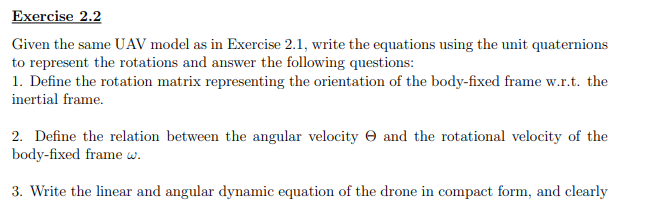

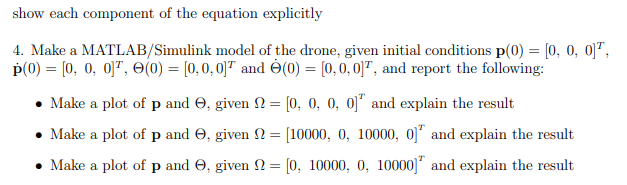

# Exercise 2.3

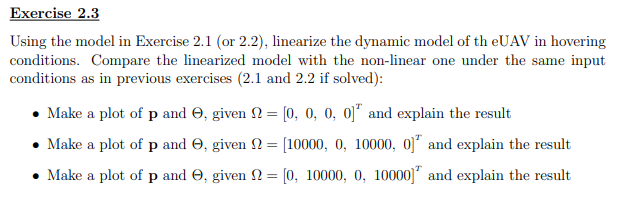

function [rotmtx] = rotx(angle)
% return the rotation matrix around x axis
% angle: degree
rotmtx = [1, 0, 0; 0, cos(angle), -sin(angle); 0, sin(angle), cos(angle)];
end

function [rotmtx] = roty(angle)
% return the rotation matrix around x axis
% angle: degree
rotmtx = [cos(angle), 0, sin(angle); 0, 1, 0; -sin(angle), 0, cos(angle)];
end

function [rotmtx] = rotz(angle)
% return the rotation matrix around x axis
% angle: degree
rotmtx = [cos(angle), -sin(angle), 0; sin(angle), cos(angle), 0; 0, 0, 1];
end